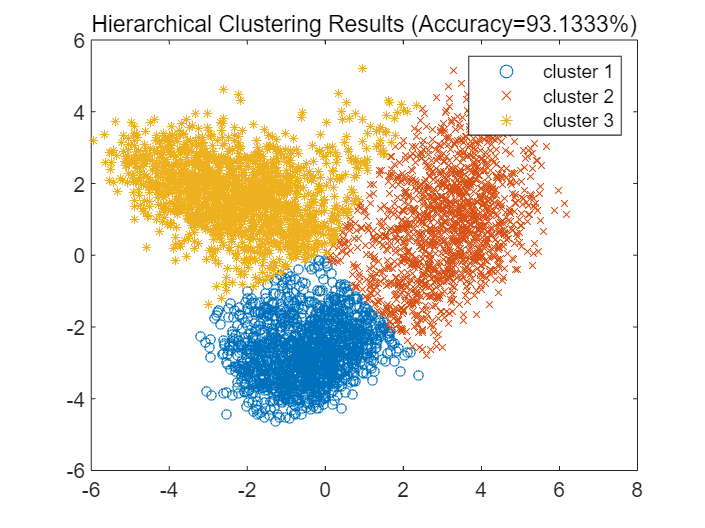

load data_PCA.mat
%in data variable,1:1500 represent digit3 1501:3000 represent
%digit6 and 3001:4500 represent digit9
data=[reshape(projection_1,[4500,1]) reshape(projection_2,[4500,1])];
label=zeros(4500,1);
label(1:1500,1)=3;
label(1501:3000,1)=6;
label(3001:4500,1)=9;

dist=pdist(data,'cosine');
%use average linkage
process=linkage(dist,'average');
correlation=cophenet(process,dist);

%expected Cluster NUmber=3
clust=cluster(process,'maxclust',3);

confus=zeros(3,3);
for i=1:size(data,1)
    if(clust(i,:)==1 && label(i,:)==3)
        confus(1,1)=confus(1,1)+1;
    elseif(clust(i,:)==1 && label(i,:)==6)
        confus(2,1)=confus(2,1)+1;
    elseif(clust(i,:)==1 && label(i,:)==9)
        confus(3,1)=confus(3,1)+1;
    elseif(clust(i,:)==2 && label(i,:)==3)
        confus(1,2)=confus(1,2)+1;
    elseif(clust(i,:)==2 && label(i,:)==6)
        confus(2,2)=confus(2,2)+1;
    elseif(clust(i,:)==2 && label(i,:)==9)
        confus(3,2)=confus(3,2)+1;
    elseif(clust(i,:)==3 && label(i,:)==3)
        confus(1,3)=confus(1,3)+1;
    elseif(clust(i,:)==3 && label(i,:)==6)
        confus(2,3)=confus(2,3)+1;
    elseif(clust(i,:)==3 && label(i,:)==9)
        confus(3,3)=confus(3,3)+1;
    end
end

accur=sum(max(confus))/size(label,1);

figure(1)
colormap("summer")
scatter(data(clust==1,1),data(clust==1,2),20,'o');hold on
scatter(data(clust==2,1),data(clust==2,2),20,'x');hold on
scatter(data(clust==3,1),data(clust==3,2),20,'*');hold on
box on
legend('cluster 1','cluster 2','cluster 3')
str = sprintf('Hierarchical Clustering Results (Accuracy=%.4f%%)',accur*100);
title(str)

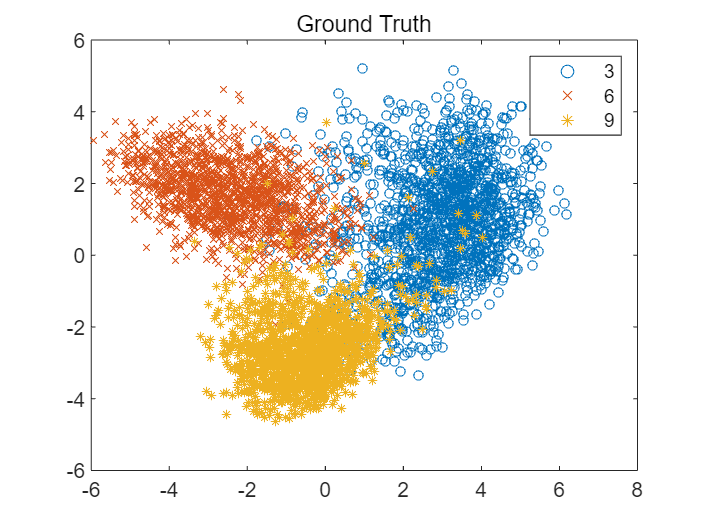


figure(2)
scatter(data(label==3,1),data(label==3,2),20,'o');hold on
scatter(data(label==6,1),data(label==6,2),20,'x');hold on
scatter(data(label==9,1),data(label==9,2),20,'*');hold off
box on
legend('3','6','9')
title('Ground Truth')

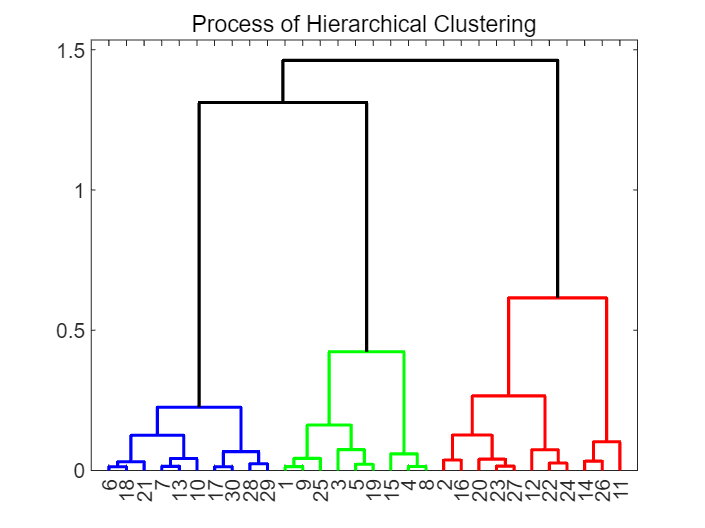


figure(3)
D = dendrogram(process,'ColorThreshold','default');
set(D,'LineWidth',1.5)
box on
title('Process of Hierarchical Clustering')